# **FRENADO MAGNÉTICO**

clear all;

%Datos iniciales

t0 = 0;             %Tiempo inicial
tf = 15;            %Tiempo final
h = 0.01;           %Diferencia de tiempo
t = t0:h:tf;        %Tiempo (vector)
m = 1250;           %Masa de la góndola
n=1000;             %Número de datos 

%Cálculo de constante producida por corrientes de Foucault
a=1.75;
esp=0.5;
cond=5.96e7;
f=5*pi/256;
u0=pi*0.014;
u=0.014;
k=36*pi*f*cond*esp*u*u/(a^4);

%Funciones
f1 = @(t, v) -9.81;            %Función para caída libre
f2 = @(t, v) -9.81-(k*v)/m;    %Función para caída en un conductor

%Alturas implicadas en la torre
hmax = 80;         %Altura máxima que alcanza la góndola
hcon = 17;         %Altura del conductor

%PARA CAÍDA LIBRE

%Para calcular la velocidad en caída libre se utiliza Runge-Kutta 4 
%con la función 1 de aceleración y estableciendo la velocidad inicial 
%como cero 
v(1) = 0;
v = RungeKutta(f1, t0, tf, h, v(1));
z = zeros(1,n);
z(1)=hmax; %la posición inicial corresponde a la altura máxima
           %(donde inicia la caída libre)

%Para calcular la posición en caída libre se utiliza el método de Euler
%para así tener la posición para cualquier instante de tiempo
for c=1:numel(t)-1
    z(c+1)=z(c)+v(c)*h;
end

%PARA POSICIÓN DEL CONDUCTOR

%Se encuentra el punto en el que la góndola toca 
%por primera vez el material conductor
posCon = 0;
for i=1:length(z)
    if (z(i) <= hcon)
        posCon = i;
        break
    end
end
t0 = posCon*h

t0 = 3.6000

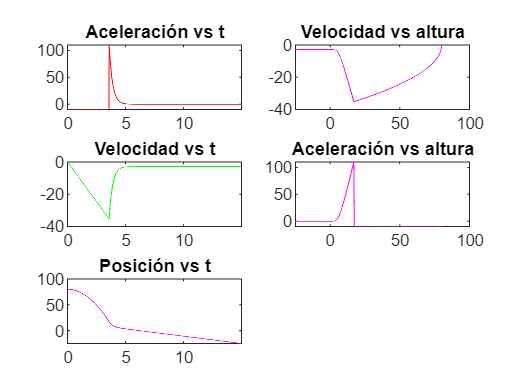


%Cálculo de la velocidad para la función de aceleración de la góndola
%en contacton con el material conductor
%Condiciones iniciales de este caso: 
%t inicial = cuando toca el conductor
%v inicial = velocidad que llevaba en caída libre antes de entrar en
%contacto
v1 = RungeKutta(f2, t0, tf, h, v(posCon));
y1 = zeros(1,length(v1));
y1(1)=hcon;

%Cálculo de la posición por medio del método de Euler
for c=1:length(v1)
    y1(c+1)=y1(c)+v1(c)*h;
end


%Vector de velocidad final compuesto de la velocidad en caída libre
%y la velocidad cuando entra en contacto con el conductor.}
vf = [v(1:posCon),v1(2:end)];


%Para obtener la posición con la velocidad final se utiliza el método de
%Euler
yf = zeros(1,length(vf));
yf(1) = hmax;
for c=1:length(vf)-1
    yf(c+1)=yf(c)+vf(c)*h;
end
t = t(1:length(vf));

%Cálculo de la aceleración a partir de la velocidad final encontrada
acel = zeros(1, length(vf));
for i=1:length(vf)-1
    acel(i) = (vf(i+1)-vf(i))/h;
end

figure, clf;

subplot(321)
plot(t,acel,"r")
title("Aceleración vs t")

subplot(323)
plot(t,vf,"g")
title("Velocidad vs t")

subplot(325)
plot(t,yf,"m")
title("Posición vs t")

subplot(322)
plot(yf,vf,"m")
title("Velocidad vs altura")

subplot(324)
plot(yf,acel,"m")
title("Aceleración vs altura")